N = 80;
n = 0:N-1;
x = (0.9).^n;
h = (0.5).^n;
f_lops = 0;
tic;
X = fft(x);
H = fft(h);
Y = X .* H;
y = ifft(Y);
time_elapsed2 = toc;
num_ops = 2 * N * log2(N); 
fprintf('总操作数: %d\n', num_ops);

总操作数: 1.011508e+03


fprintf('执行时间 (秒): %.6f\n', time_elapsed2);

执行时间 (秒): 0.004218


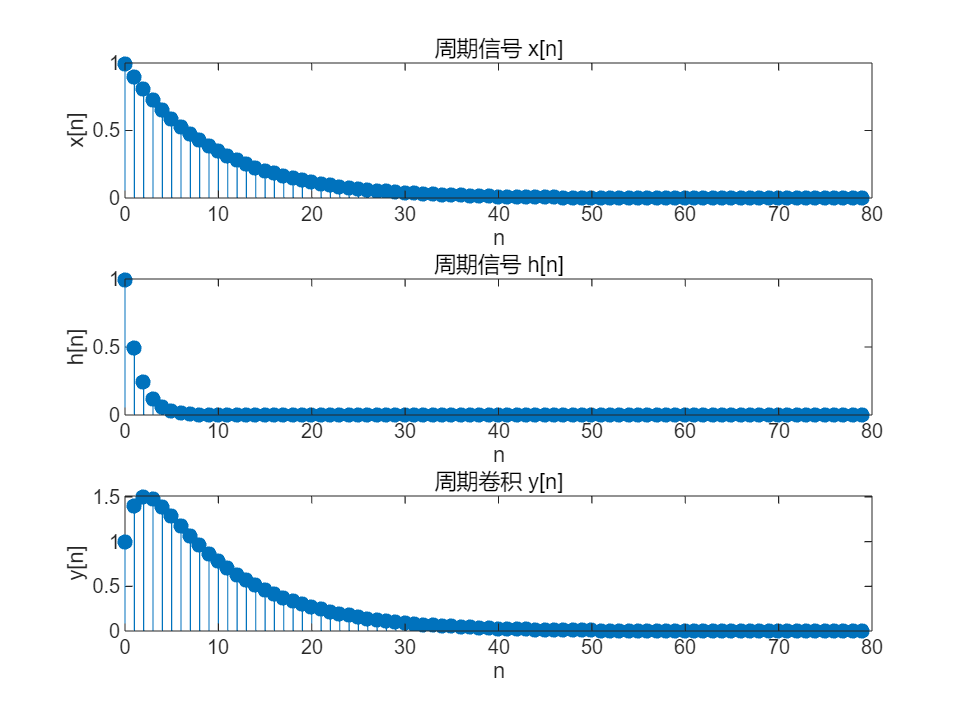

f_80f = num_ops;
figure;
subplot(3,1,1);
stem(n, x, 'filled');
title('周期信号 x[n]');
xlabel('n');
ylabel('x[n]');
subplot(3,1,2);
stem(n, h, 'filled');
title('周期信号 h[n]');
xlabel('n');
ylabel('h[n]');
subplot(3,1,3);
stem(n, real(y), 'filled'); 
title('周期卷积 y[n]');
xlabel('n');
ylabel('y[n]');

f80f = time_elapsed2

f80f = 0.0042